## Transformada Rapida de Fourier (FFT)

#### Realizado por: Enrique Rodriguez, Miguel Angel Vallejo, Francisco Lopez-Alvarado, Bernardo Ordas y Javier Viseras

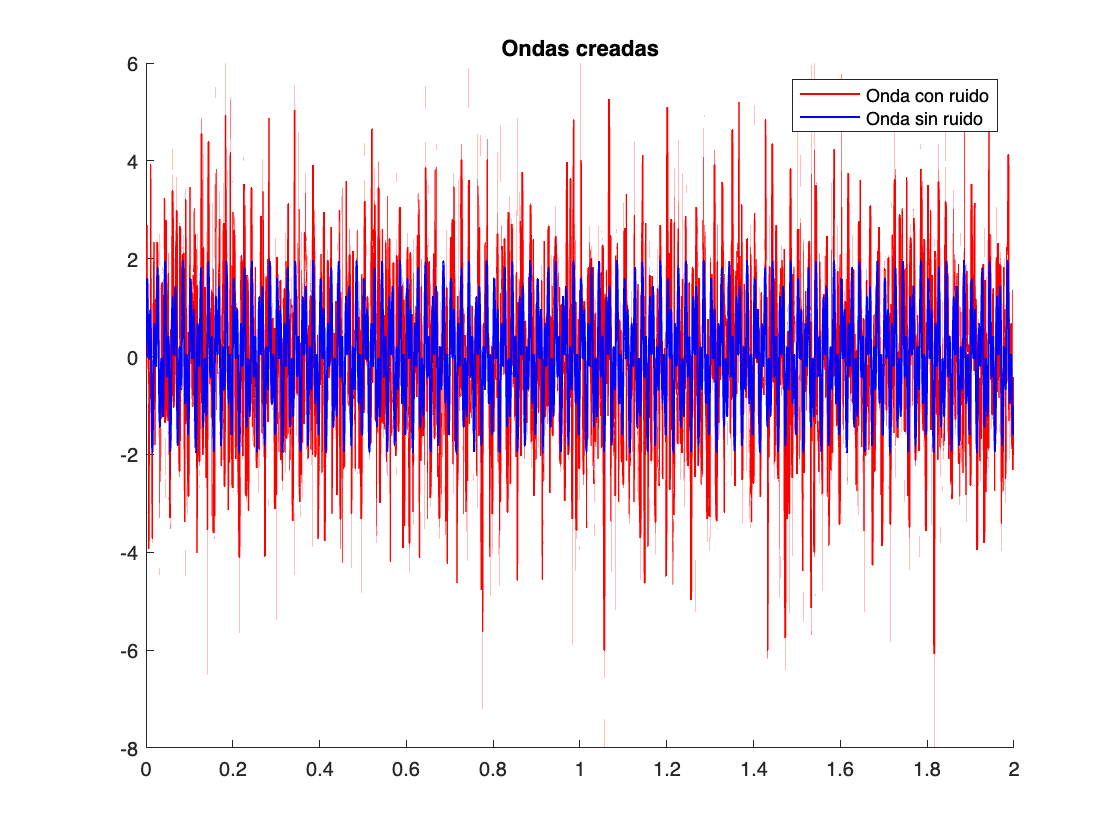

clc;
frec_muestreo = 1000; 
dt = 1/frec_muestreo;
n = 2;
t = 0:dt:n-dt;  

onda_SR = sin(2*pi*50*t) + sin(2*pi*120*t);
onda_CR = onda_SR + 1.5*randn(size(t)); 
hold on;
title('Ondas creadas');
plot(t, onda_CR, 'Color', 'Red', 'LineWidth', 1, 'DisplayName', 'Onda con ruido');  
plot(t, onda_SR, 'Color', 'blue', 'LineWidth', 1, 'DisplayName', 'Onda sin ruido');  
legend();
hold off;


m = length(onda_CR);
fft_ondar = Fast_Fourier_Transform(onda_CR);

Los datos no son potencia de 2, llenando 0s hasta completar


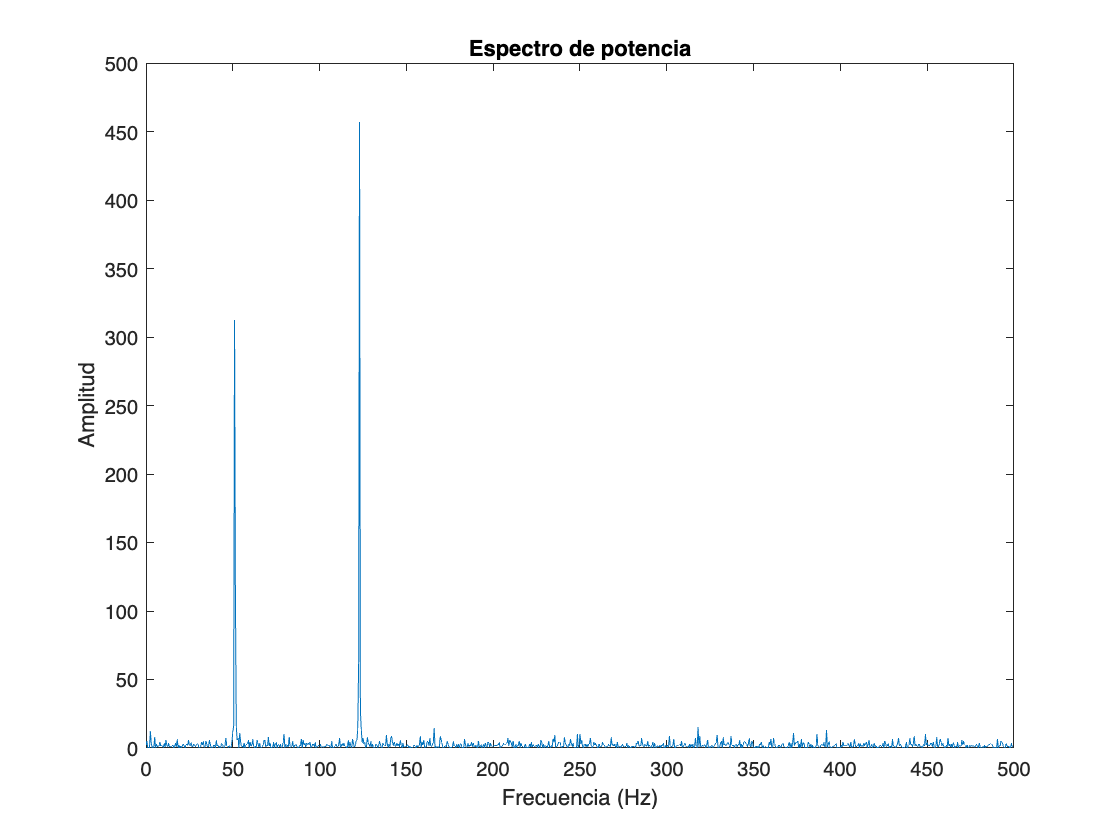

power_spectrum = fft_ondar .* conj(fft_ondar) / m; 
L = 1:floor(m/2);
freq_x = 1 / (dt * m) * (0:m);  
plot(freq_x(L), power_spectrum(L));
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Espectro de potencia');




% Consuyamos un filtro para obtener las frecuencias originales
index = power_spectrum > 300;
frecuencias = index .* power_spectrum;
mitad_frec = freq_x(L);
frecuencias = freq_x(find(frecuencias ~= 0));
frecuencias = frecuencias(1:2)

frecuencias =     51   123


## Aplicacion con ondas de audio

### Generar sonido con ruido

fs = 44100; 
dur = 60; 
f_clean = 440; 
amplitud_clean = 0.8; 
amplitud_ruido = 0.2; 

t = 0:1/fs:dur-1/fs; 
x_clean = amplitud_clean * sin(2*pi*f_clean*t);

ruido = amplitud_ruido * randn(size(t)); 

x_with_noise = x_clean + ruido;

filename = 'senal_con_ruido.wav';
audiowrite(filename, x_with_noise, fs);

## FFT del sonido con ruido

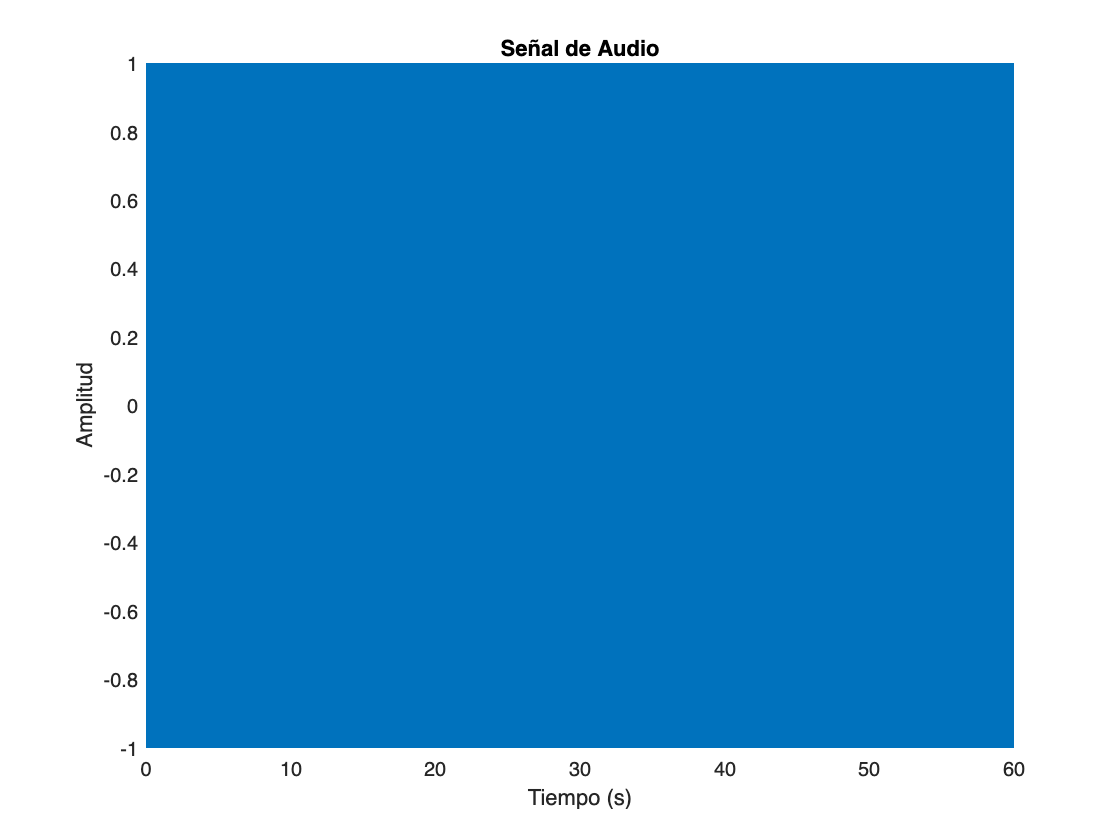

clear all
[data,fs] = audioread('senal_con_ruido.wav');
t = (0:length(data)-1) / fs;  
plot(t, data);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal de Audio');



data = transpose(data)

data =     0.1440   -0.3960    0.0422    0.1463   -0.1012    0.2989    0.3486    0.2324    0.6962    0.3335   -0.0237    0.5123    0.5834    0.6132    0.7265    0.8347    0.5083    0.7609    0.4299    0.5978    0.6718    1.0000    0.9694    0.8280    0.8274    1.0000    0.5938    0.5695    1.0000    0.8756    0.6039    0.8830    0.8928    0.8320    0.7552    0.6609    0.5096    0.2109    0.7243    0.8683    0.5343    0.7155    0.0825    0.2901    0.7728    0.0214    0.1137    0.6134    0.2808   -0.1557


dt = 1/fs;
m = length(data);
audio_fft = Fast_Fourier_Transform(data);

Los datos no son potencia de 2, llenando 0s hasta completar


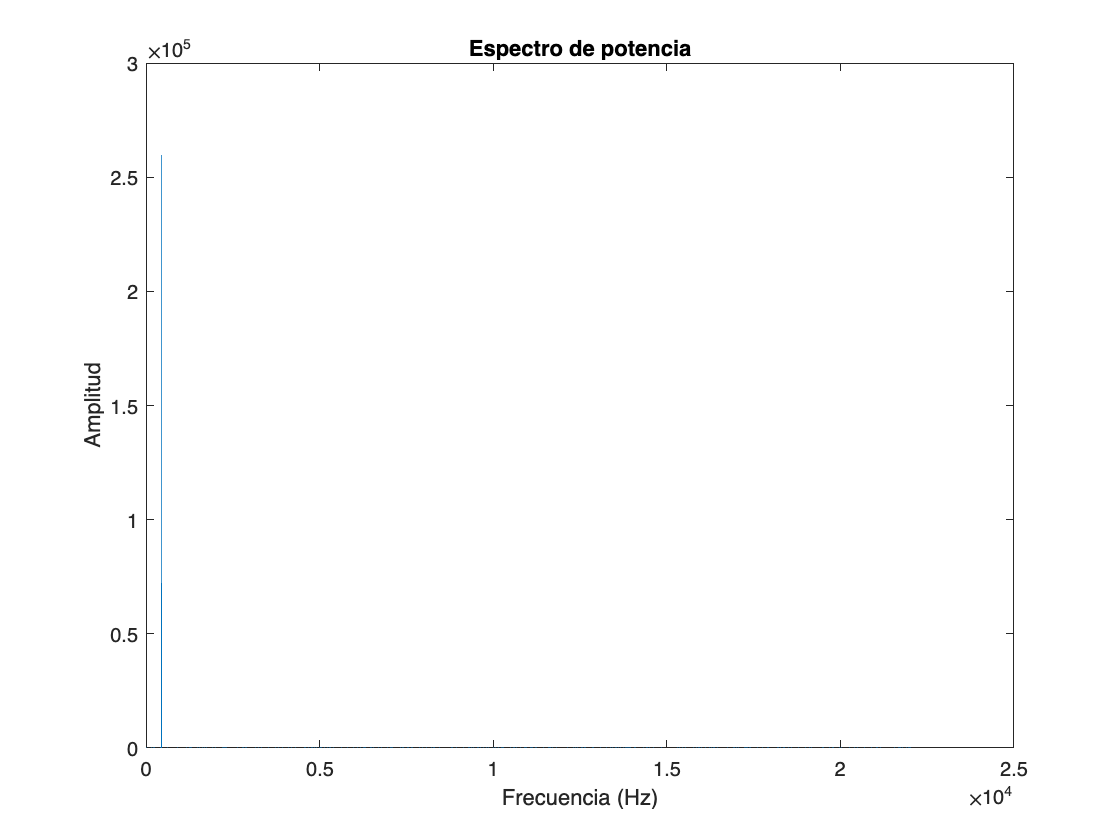

m = length(audio_fft);
power_spectrum = audio_fft .* conj(audio_fft) / m; 
L = 1:floor(m/2);
freq_x = 1 / (dt * m) * (0:m);  
plot(freq_x(L), power_spectrum(L));
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Espectro de potencia');


% Consuyamos un filtro para obtener las frecuencias originales
index = power_spectrum > 300;
frecuencias = index .* power_spectrum;
mitad_frec = freq_x(L);
frecuencias = freq_x(find(frecuencias ~= 0));
frecuencias = frecuencias(1);
dur = length(data)/fs;
% generar sonido
t = 0:1/fs:dur-1/fs;
f = sin(2*pi*frecuencias*t);
audiowrite('senal_limpia.wav',f, fs);


function  X = Fast_Fourier_Transform(data)
    N = length(data); 
    if sqrt(N) ~= floor(sqrt(N))
        disp('Los datos no son potencia de 2, llenando 0s hasta completar')
        data = fill_0s(data);
        N = length(data); 
    end 

    X = zeros(size(data));
    X = fft_recursive(data, N);

end 

function X =  fft_recursive(x, N)   
    if length(x) == 1
        X = x;
    else
        x_par =fft_recursive(x(1:2:N), N/2);
        x_impar = fft_recursive(x(2:2:N), N/2);
        W = exp(-1i * 2 * pi / N);
        for k = 1:N/2
            X(k) = x_par(k) + W^(k-1) * x_impar(k);
            X(k+N/2) = x_par(k) - W^(k-1) * x_impar(k);
    
        end 
    end
end 

function X = fill_0s(x)
    N = length(x);
    M = 2^(ceil(log2(N)));
    k = M-N;
    array0s = zeros(1, k); 
    X = [x, array0s];
end 